#                        Blind Source Separation

##                                            HW8-Section-1

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/03/08   

clear; clc; close all;

## Load Data:

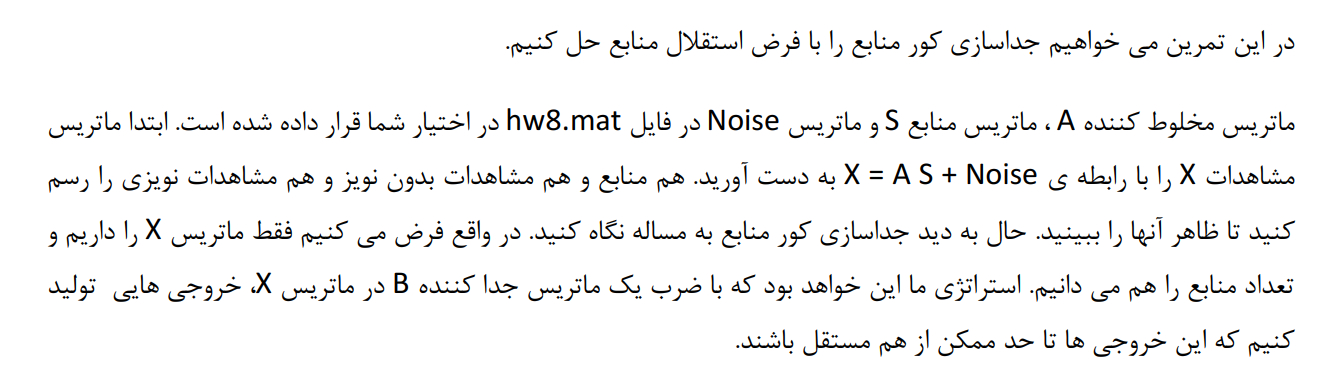

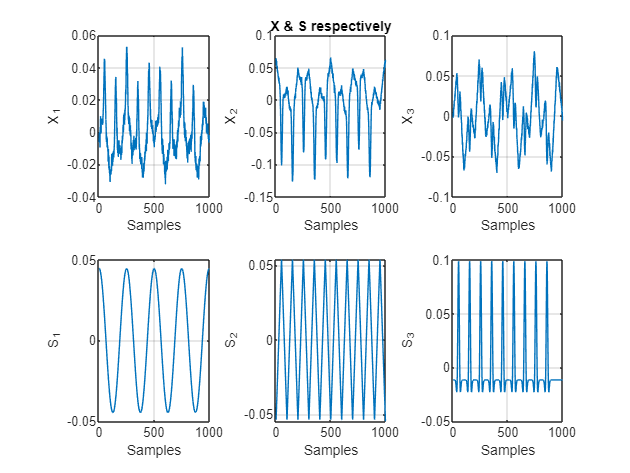

Data_hw8 = load("hw8.mat");

A = Data_hw8.A;
S = Data_hw8.S;
Noise = Data_hw8.Noise;

X = A*S+Noise;

figure()
subplot(2,3,1)
plot(X(1,:))
grid on
xlabel("Samples")
ylabel("X_1")


subplot(2,3,2)
plot(X(2,:))
grid on
xlabel("Samples")
ylabel("X_2")
title("X & S respectively")

subplot(2,3,3)
plot(X(3,:))
grid on
xlabel("Samples")
ylabel("X_3")





subplot(2,3,4)
plot(S(1,:))
grid on
xlabel("Samples")
ylabel("S_1")

subplot(2,3,5)
plot(S(2,:))
grid on
xlabel("Samples")
ylabel("S_2")

subplot(2,3,6)
plot(S(3,:))
grid on
xlabel("Samples")
ylabel("S_3")

## ICA implementation:


% Random B:

B   = randn(size(inv(A)));
[B,~]   = eig(B*B');  % Enforce Orthogonality
y = B*X;
Num_of_Channels = size(y);
Score_Func_y = zeros(size(y));
K_y = zeros(Num_of_Channels(1,1) , M,length(y));

mu = 1e4;

IterMax = 300;
Error_Iter = zeros(1,IterMax);
MIN_ERR = inf;
for i=1:IterMax

%  for n=1:Num_of_Channels(1,1)
%     K_y(n,:,:) = [ones(size(y(n,:)));y(n,:);y(n,:).^2;y(n,:).^3;y(n,:).^4;y(n,:).^5]; 
%  end   

 % Estimation of Score Function:
 [Theta_hat , Score_Func_y ] = Theta_Calc_Kernel(y);
%  for n=1:Num_of_Channels(1,1)
%     Score_Func_y(n,:) = Theta_hat(n,:)*squeeze(K_y(n,:,:));
%  end

 % Update B:
 StepSize = ( Score_Func_y*X' )/length(X) - pinv(B');
 StepSize = normalize(StepSize,2,"norm");
 B        = B - mu*StepSize  ;
 % Enforce Orthogonality:
 for m=2:length(B)
    indexes = 1:m;
    indexes(m) = [];
    B(:,m)  = (eye(size(B)) -  B(:,indexes)*B(:,indexes)'   )*B(:,m)  ;
 end
 B_Norm = normalize(B, 1, 'norm');

 % New y calc:
 y = B_Norm'*X;
 B = B_Norm;


 % Remove Permutation:
%  [Errors_ICA,y]  = Perm_AMP_Disamb(y,S);
 Errors_ICA = norm(y-S)/norm(S);
 Error_Iter(i) = min(Errors_ICA);

 if(MIN_ERR > Error_Iter(i))
     y_Best = y;
     Index_Best = i;
     MIN_ERR = Error_Iter(i);
 end
 
 
end

disp("calculated Error Equals to: "+min(Errors_ICA))

calculated Error Equals to: 1.7463


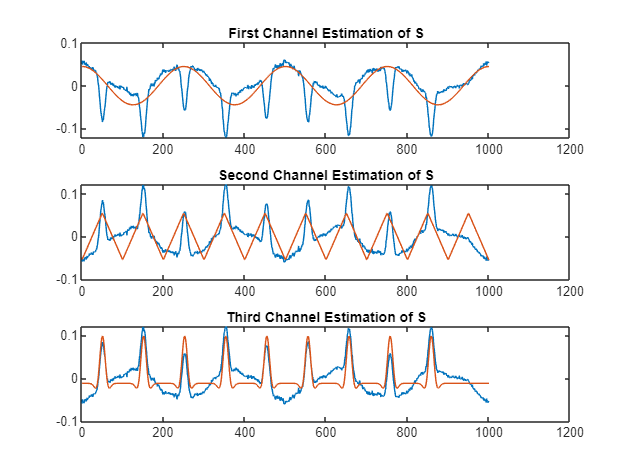

% Recovered S_hat:
y = y_Best;

figure()
subplot(3,1,1)
plot(y(1,:))
hold on
plot(S(1,:))
hold off
title("First Channel Estimation of S")


subplot(3,1,2)
plot(y(2,:))
hold on
plot(S(2,:))
hold off
title("Second Channel Estimation of S")


subplot(3,1,3)
plot(y(3,:))
hold on
plot(S(3,:))
hold off
title("Third Channel Estimation of S")

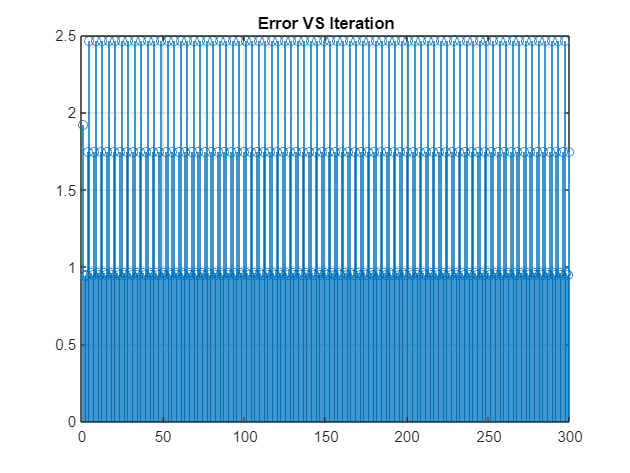


figure()
stem(Error_Iter)
grid on
title("Error VS Iteration")

## Implementation with ICA Deflation:  

Just whitening first and then performing for each row of B independently:

% Whitening:
[U , Gamma] = eig(X*X');
W = Gamma^(-0.5);
Z = W*U'*X;




B   = randn(size(inv(A)));
[B,~]   = eig(B*B');  % Enforce Orthogonality
y = B*Z;

Num_of_Channels = size(y);
Score_Func_y = zeros(size(y));
K_y = zeros(Num_of_Channels(1,1) , M,length(y));

mu = 1e2;

IterMax = 1250;
Error_Iter_deflate = zeros(1,IterMax);
MIN_ERR = inf;
for p=1:IterMax

   
    for i=1:length(B) % Each Row
         % Estimation of Score Function:
         [Theta_hat , Score_Func_y ] = Theta_Calc_Kernel(y(i,:));
         StepSize = ( Score_Func_y*Z' )/length(Z) ;
        %  StepSize = normalize(StepSize,2,"norm");
         B(i,:)        = B(i,:) - mu*StepSize  ;
         B(i,:)        =  ( eye(size(B)) - B(1:i-1,:)'*B(1:i-1,:)   )* B(i,:)';  % Orthogonality
         B(i,:)  = B(i,:)/norm(B(i,:));
    end
    y = B*Z;

 % Remove Permutation:
%  [Errors_ICA,y]  = Perm_AMP_Disamb(y,S);
 Errors_ICA = norm(y-S)/norm(S);
 Error_Iter_deflate(p) = min(Errors_ICA);

 if(MIN_ERR > Error_Iter_deflate(p))
     y_Best = y;
     Index_Best = p;
     MIN_ERR = Error_Iter_deflate(p);
 end
 
 
end



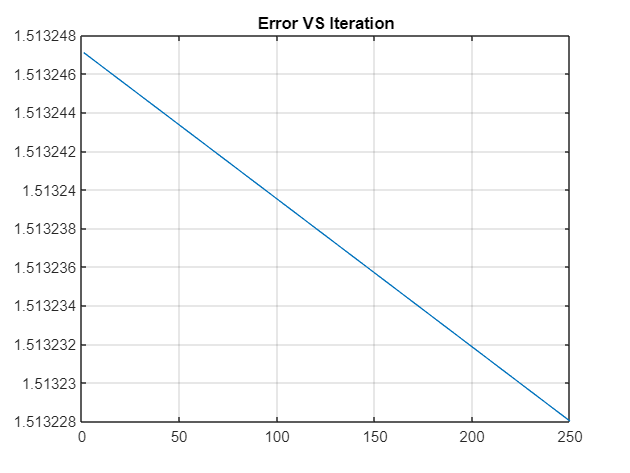


figure()
plot(Error_Iter_deflate)
grid on
title("Error VS Iteration")

disp("calculated Error Equals to: "+min(Errors_ICA))

calculated Error Equals to: 1.5132


disp(abs(B*W*A))

    0.6384    1.1808    1.4166
    0.1072    0.5190    0.2491
    1.2456    0.5540    0.0590



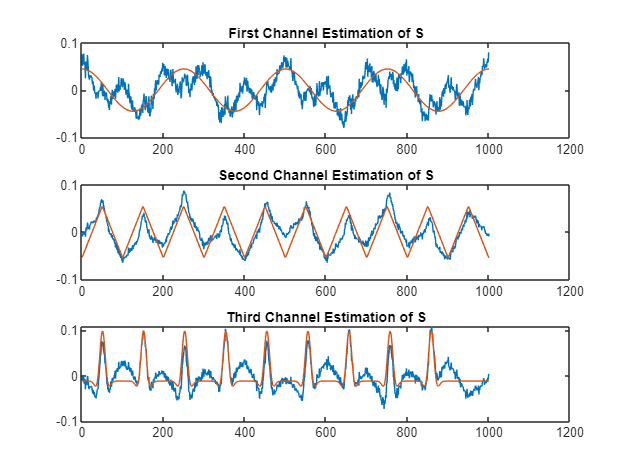


% Recovered S_hat:
y = y_Best;




figure()
subplot(3,1,1)
plot(y(3,:))% Permutaion
hold on
plot(S(1,:))
hold off
title("First Channel Estimation of S")


subplot(3,1,2)
plot(y(2,:))
hold on
plot(S(2,:))
hold off
title("Second Channel Estimation of S")


subplot(3,1,3)
plot(y(1,:))
hold on
plot(S(3,:))
hold off
title("Third Channel Estimation of S")

Y_True = [y(3,:) ; y(2,:) ; y(1,:)   ] ;
% Calc True Error:
Error_FInal = norm(Y_True  - S)/norm(S);
disp("Final Error AFter Removing Permutaion : "+Error_FInal)

Final Error AFter Removing Permutaion : 0.84354


## Functions:

function [Theta_hat, PSI_hat] = Theta_Calc_Kernel(y)
% Theta Hat Calculation Function for Kernel Method+MSE:

Coeff = [0,1,2,3,4,5];
N = length(Coeff);
Num_of_Channels = size(y(:,1));

Theta_hat        = zeros(Num_of_Channels(1,1),N);
PSI_hat = zeros(size(y));
% Moment_Matrix    = zeros(N,N);
% Expected_Kernel_prime   = zeros(N,1);

    for n=1:Num_of_Channels(1,1)
        y_temp = y(n,:);
        ky = [ones(size(y_temp)) ; y_temp; y_temp.^2; y_temp.^3; y_temp.^4; y_temp.^5   ];
        ky_prime = [zeros(size(y_temp))  ; ones(size(y_temp)); 2*y_temp; 3*y_temp.^2; 4*y_temp.^3; 5*y_temp.^4];
%         for i=0:N-1
%             for j=0:N-1
%                 Moment_Matrix(j+1,i+1) = mean(y(n,:).^(j+i));
%             end
%         end
%         for i=2:N
%             Expected_Kernel_prime(i,1) = Coeff(i)*mean(y(n,:).^(i-2));
%         end
    
    Theta_hat(n,:) = pinv(ky*ky')/length(y_temp)*mean(ky_prime,2); 
    PSI_hat(n,:)   = Theta_hat(n,:)*ky;
    end

end


function [Erroes_B,B_Hat_Chosen]  = Perm_AMP_Disamb(B_Hat,S_Amp) %% Perm_AMP_Disamb
Perm_1 = B_Hat;
Perm_2 = -B_Hat;
Perm_3 = B_Hat([end, 1:end-1],:);
Perm_4 = -B_Hat([end, 1:end-1],:);
Perms = { Perm_1,Perm_2,Perm_3,Perm_4  };
% Estimate S:
S_hat_1 = Perm_1;
S_hat_1_Normalised = S_hat_1/norm(S_hat_1,'fro');
S_hat_2 = Perm_2;
S_hat_2_Normalised = S_hat_2/norm(S_hat_2,'fro');
S_hat_3 = Perm_3;
S_hat_3_Normalised = S_hat_3/norm(S_hat_3,'fro');
S_hat_4 = Perm_4;
S_hat_4_Normalised = S_hat_4/norm(S_hat_4,'fro');
% Calc Error:
S_Amp_Normalized = S_Amp/norm(S_Amp,'fro');

Error_1 = (norm((S_hat_1_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 
Error_2 = (norm((S_hat_2_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 
Error_3 = (norm((S_hat_3_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 
Error_4 = (norm((S_hat_4_Normalised)-(S_Amp_Normalized),'fro'))^2/norm((S_Amp_Normalized),"fro")^2 ; 

S_hat_cell = {S_hat_1_Normalised,S_hat_2_Normalised,S_hat_3_Normalised,S_hat_4_Normalised};

Erroes_B = [Error_1,Error_2,Error_3,Error_4];
[ ~, index] = min(Erroes_B);
B_Hat_Chosen = Perms{index} ;%S_hat_cell{index};
end
